# Nonlinear Timoshenko beam

We compute SSM compute for a geometrically nonlinear Timoshenko Beam

clear all; 

### Generate model

nElements = 4;
isViscoelastic = false;
[M,C,K,fnl,fext,outdof] = build_model(nElements,isViscoelastic);
n = length(M);

node_idx = nElements/4+1;
mDOFs = 5*(node_idx-1)-3+[1, 4]; % translational DOFs
rDOF = 5*(node_idx-1)-3+3;       % rotational DOF

Ma = M;
mass = 80; 
moment_of_inertia = mass*250*250;
Ma(mDOFs,mDOFs) = Ma(mDOFs,mDOFs) + mass*eye(2,2); % adding mass to translational DOF
Ma(rDOF,rDOF)   = Ma(rDOF,rDOF)+moment_of_inertia;

### Dynamical system setup

DSorder = 2;
DS = DynamicalSystem(DSorder);
set(DS,'M',Ma,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
epsilon = 7e-4;
kappas = [-1; 1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas, epsilon);

### Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.686725e-04
modal damping ratio for 2 mode is 5.409783e-04
modal damping ratio for 3 mode is 3.025786e-03
modal damping ratio for 4 mode is 6.645833e-03
modal damping ratio for 5 mode is 5.445036e-03

 The first 10 eigenvalues are given as 
  -0.0004 + 2.2562i
  -0.0004 - 2.2562i
  -0.0039 + 7.2301i
  -0.0039 - 7.2301i
  -0.1206 +39.8735i
  -0.1206 -39.8735i
  -0.3679 +55.3614i
  -0.3679 -55.3614i
  -0.3968 +72.8771i
  -0.3968 -72.8771i



**Choose Master subspace**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
masterModes = [1,2,3,4]; 
S.choose_E(masterModes);

No (near) outer resonances detected in the (truncated) spectrum
sigma_out = 1042
(near) inner resonance detected for the following combination of master eigenvalues
     1     0     1     1
     2     1     0     0
     1     0     2     2
     2     1     1     1
     3     2     0     0
     1     0     3     3
     2     1     2     2
     3     2     1     1
     4     3     0     0
     1     0     4     4
     2     1     3     3
     3     2     2     2
     4     3     1     1
     5     4     0     0
     0     1     1     1
     1     2     0     0
     0     1     2     2
     1     2     1     1
     2     3     0     0
     0     1     3     3
     1     2     2     2
     2     3     1     1
     3     4     0     0
     0     1     4     4
     1     2     3     3
     2     3     2     2
     3     4     1     1
     4     5     0     0
     0     0     2     1
     1     1     1     0
     0     0     3     2
     1     1     2     1
     2     2     1     0
     0    

### Forced response curves using SSMs

Setup options

set(S.Options, 'reltol', 0.5,'IRtol',0.08,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^8, 'nRho', 200, 'nPar', 200, 'nPsi', 100, 'rhoScale', 2 )
set(S.contOptions, 'h_max', 10,'PtMX',350,'h_min',1e-3);
set(S.FRCOptions, 'outdof',outdof+1)

Choose frequency range

omegaRange = [2.1, 2.7];

## Primary resonance of the first mode

We first consider the case that $\Omega\approx\omega_1$.

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     5     0
     0     2     6     0
     2     0     6     1
     3     1     5     0
     5     0     4     0
     0     2     7     1
     1     3     6     0
     0     2     0     5
     2     0     0     6
     0     2     1     6
     0     5     0     4
     1     3     0     5
     2     0     1     7
     3     1     0     6
     0     1     8     0
     2     0     7     0
     0     2     0     7
     1     0     0     8
     0     0    10     0
     0     0     0    10

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.3679 +55.3614i
  -0.3679 +55.3614i
  -0.3679 -55.3614i


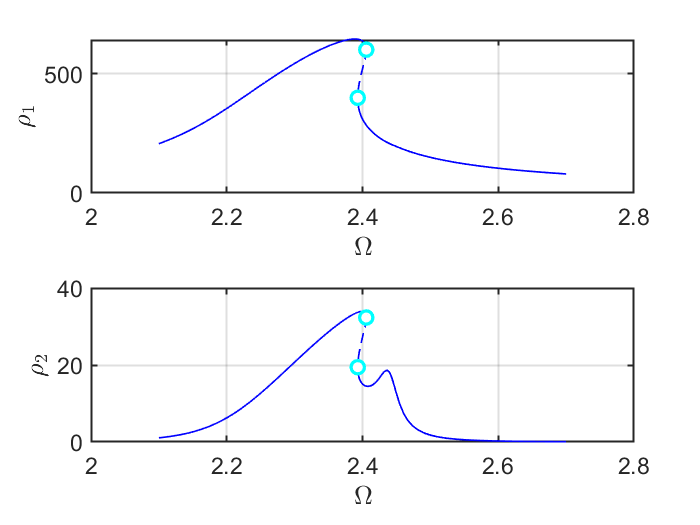

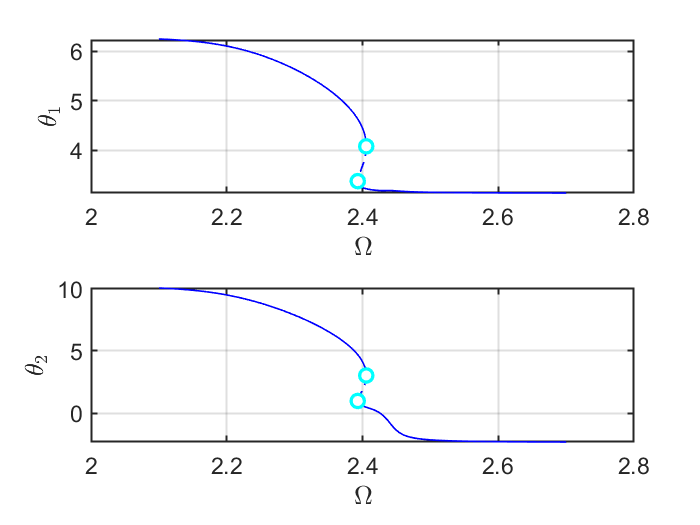

the forcing frequency 2.1000e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1033e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1098e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1159e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1219e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1275e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1329e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1382e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1432e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1481e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequenc

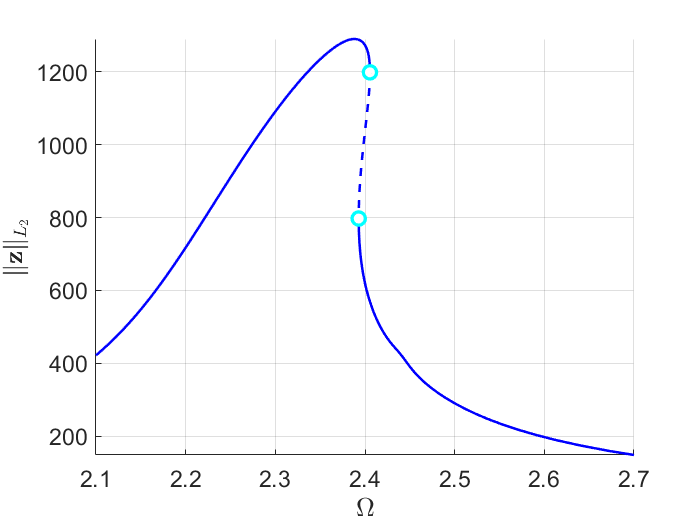

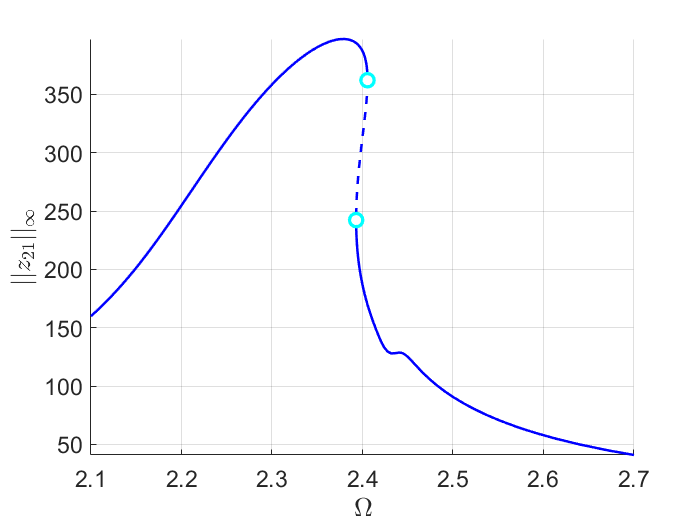

set(S.FRCOptions, 'nCycle',500, 'initialSolver', 'fsolve');
set(S.FRCOptions, 'coordinates', 'polar');

% computation at order 3
order = 3; % Approximation order
start = tic;
FRC_LD_O3 = S.SSM_isol2ep('isol-ld-3',masterModes, order, [1 3], 'freq', omegaRange,outdof+1);

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     5     0
     0     2     6     0
     2     0     6     1
     3     1     5     0
     5     0     4     0
     0     2     7     1
     1     3     6     0
     0     2     0     5
     2     0     0     6
     0     2     1     6
     0     5     0     4
     1     3     0     5
     2     0     1     7
     3     1     0     6
     0     1     8     0
     2     0     7     0
     0     2     0     7
     1     0     0     8
     0     0    10     0
     0     0     0    10

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.3679 +55.3614i
  -0.3679 +55.3614i
  -0.3679 -55.3614i


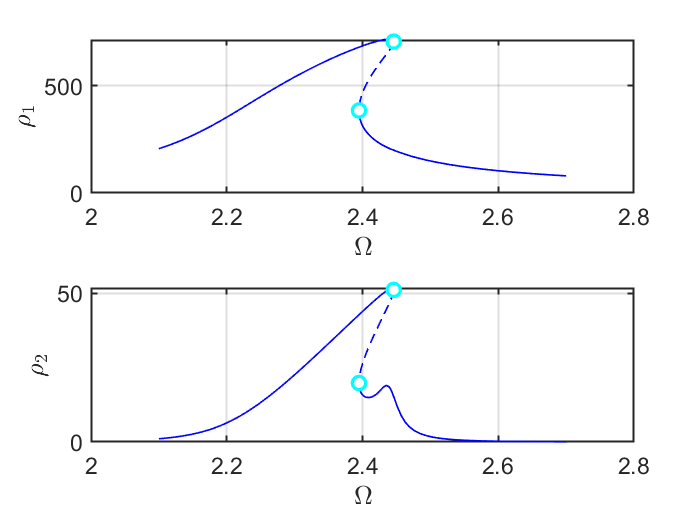

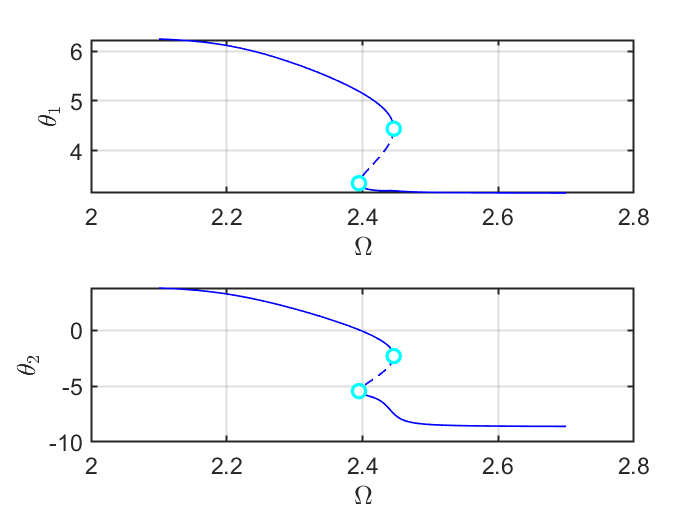

the forcing frequency 2.1000e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1013e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1079e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1142e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1202e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1259e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1315e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1368e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1419e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1468e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequenc

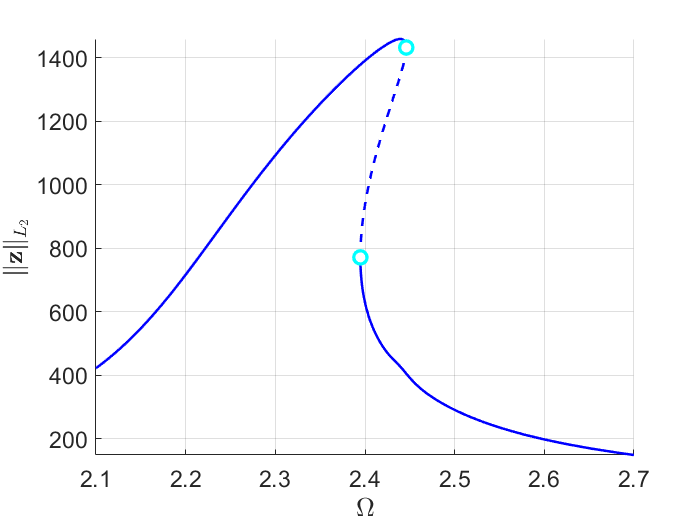

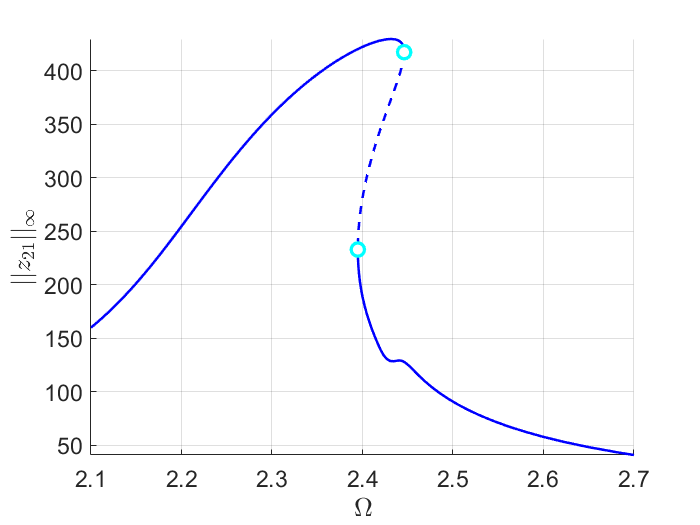

timings.FRC_ND_O3 = toc(start);

% increase order to check convergence
sol = ep_read_solution('isol-ld-3.ep',1);
start = tic;
FRC_LD_O5 = S.SSM_isol2ep('isol-ld-5',masterModes, order+2, [1 3],...
    'freq', omegaRange,outdof+1,{sol.p,sol.x});

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     5     0
     0     2     6     0
     2     0     6     1
     3     1     5     0
     5     0     4     0
     0     2     7     1
     1     3     6     0
     0     2     0     5
     2     0     0     6
     0     2     1     6
     0     5     0     4
     1     3     0     5
     2     0     1     7
     3     1     0     6
     0     1     8     0
     2     0     7     0
     0     2     0     7
     1     0     0     8
     0     0    10     0
     0     0     0    10

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.3679 +55.3614i
  -0.3679 +55.3614i
  -0.3679 -55.3614i


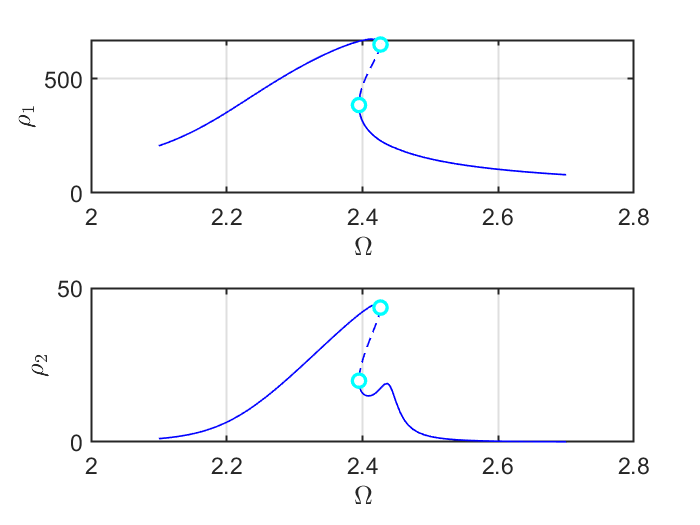

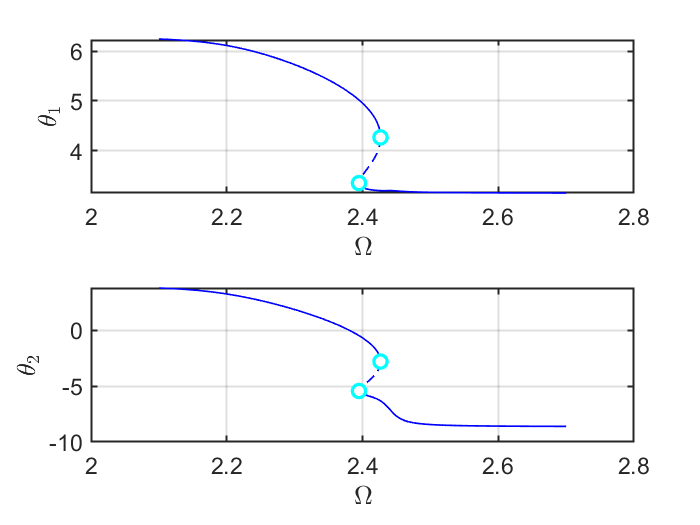

the forcing frequency 2.1000e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1002e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1069e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1132e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1192e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1250e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1306e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1359e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1411e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1460e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequenc

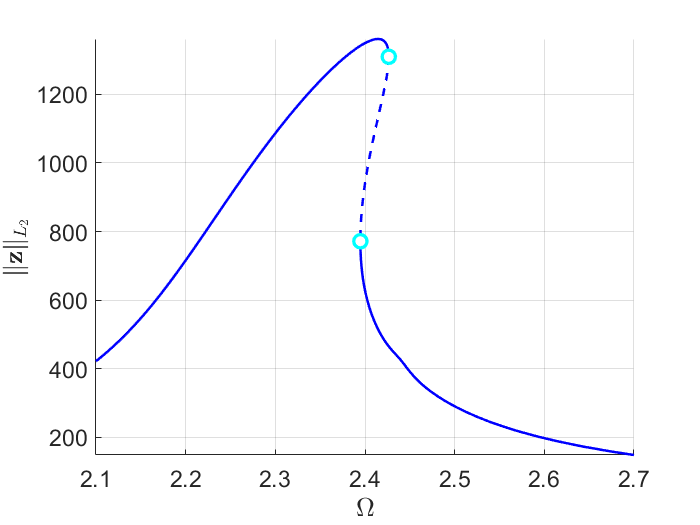

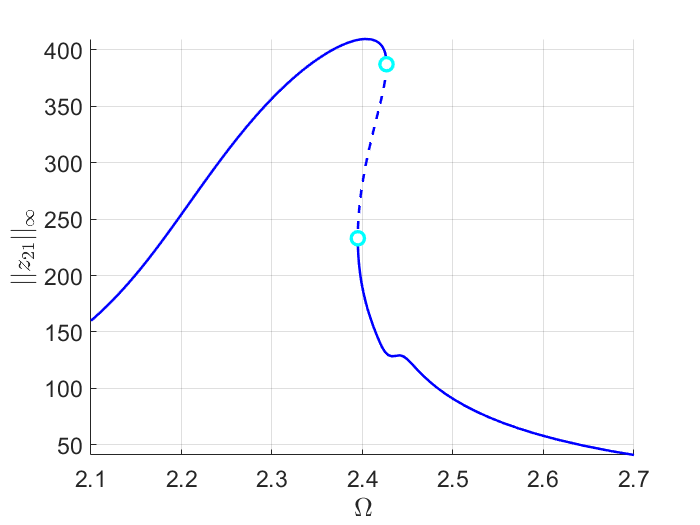

timings.FRC_ND_O5 = toc(start);

start = tic;
FRC_LD_O7 = S.SSM_isol2ep('isol-ld-7',masterModes, order+4, [1 3],...
    'freq', omegaRange,outdof+1,{sol.p,sol.x});

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     5     0
     0     2     6     0
     2     0     6     1
     3     1     5     0
     5     0     4     0
     0     2     7     1
     1     3     6     0
     0     2     0     5
     2     0     0     6
     0     2     1     6
     0     5     0     4
     1     3     0     5
     2     0     1     7
     3     1     0     6
     0     1     8     0
     2     0     7     0
     0     2     0     7
     1     0     0     8
     0     0    10     0
     0     0     0    10

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.3679 +55.3614i
  -0.3679 +55.3614i
  -0.3679 -55.3614i


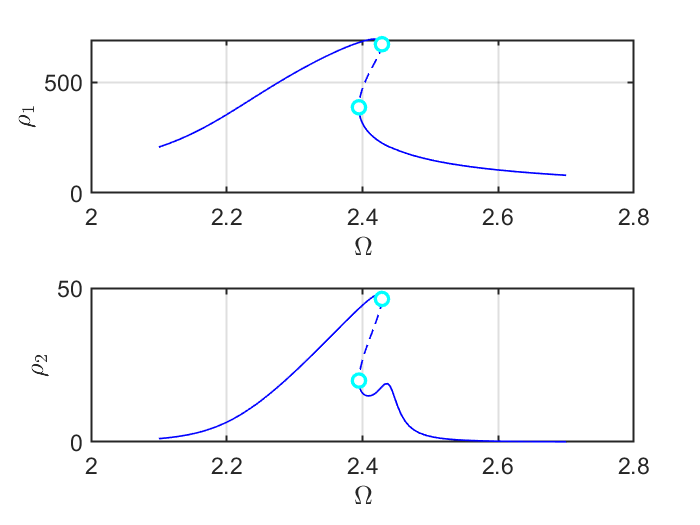

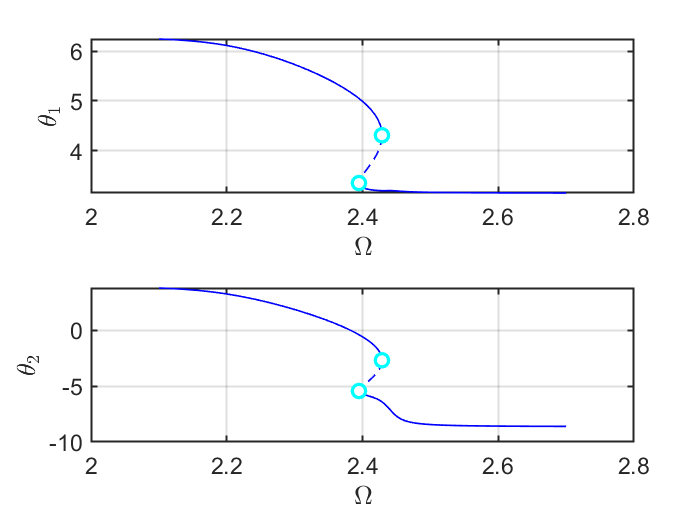

the forcing frequency 2.1000e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1009e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1076e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1139e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1199e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1256e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1312e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1365e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1416e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1466e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequenc

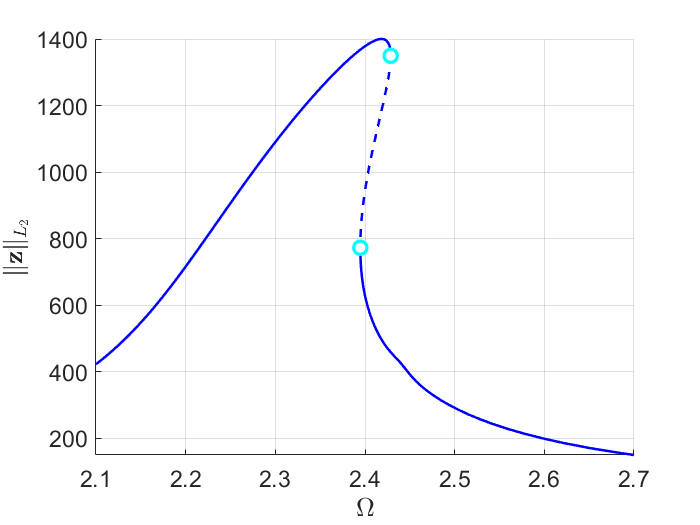

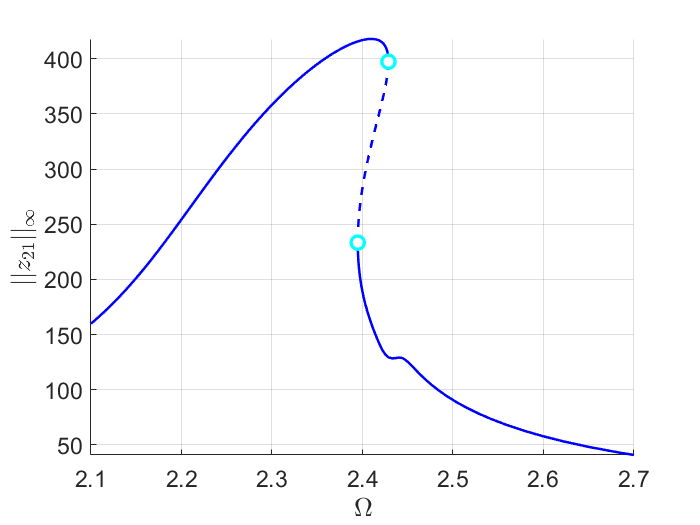

timings.FRC_ND_O7 = toc(start);

start = tic;
FRC_LD_O9 = S.SSM_isol2ep('isol-ld-9',masterModes, order+6, [1 3],...
    'freq', omegaRange,outdof+1,{sol.p,sol.x});

(near) outer resonance detected for the following combination of master eigenvalues
     2     0     5     0
     0     2     6     0
     2     0     6     1
     3     1     5     0
     5     0     4     0
     0     2     7     1
     1     3     6     0
     0     2     0     5
     2     0     0     6
     0     2     1     6
     0     5     0     4
     1     3     0     5
     2     0     1     7
     3     1     0     6
     0     1     8     0
     2     0     7     0
     0     2     0     7
     1     0     0     8
     0     0    10     0
     0     0     0    10

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 +39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.1206 -39.8735i
  -0.3679 +55.3614i
  -0.3679 +55.3614i
  -0.3679 -55.3614i


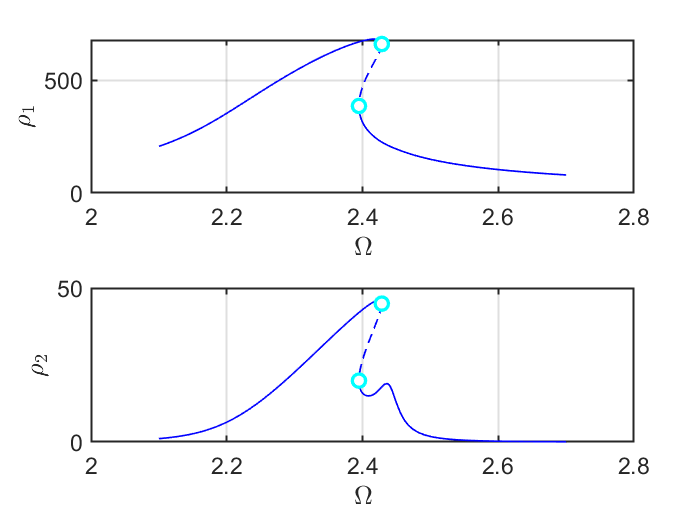

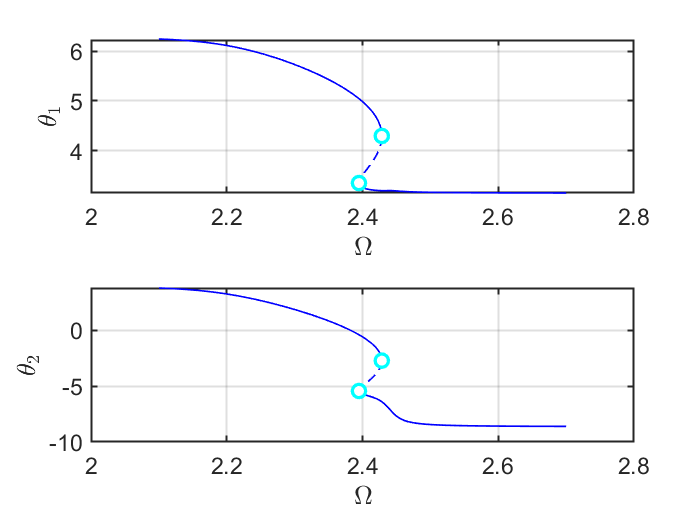

the forcing frequency 2.1000e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1007e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1074e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1137e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1197e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1255e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1310e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1363e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1414e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequency 2.1464e+00 is nearly resonant with the eigenvalue -3.8056e-04 + i2.2562e+00
the forcing frequenc

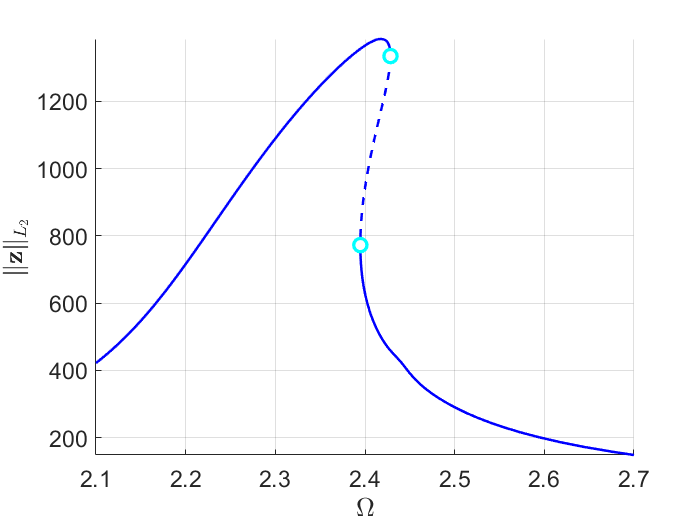

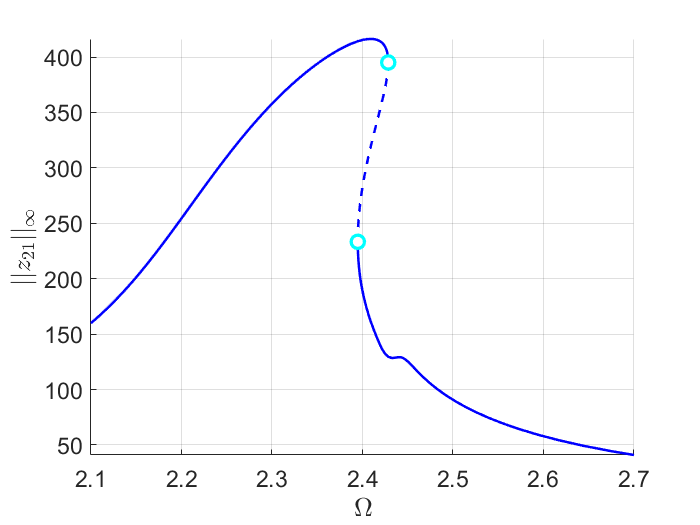

timings.FRC_ND_O9 = toc(start);

FRC_LD_O11 = S.SSM_isol2ep('isol-ld-11',masterModes, order+8, [1 3],...
    'freq', omegaRange,outdof+1,{sol.p,sol.x});

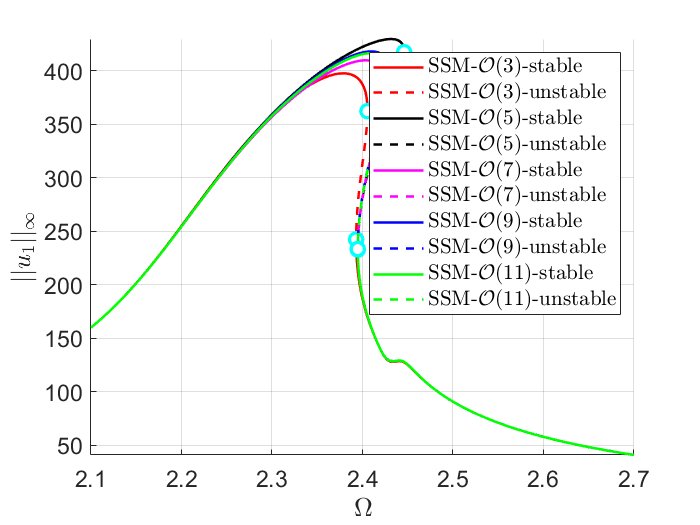

timings.FRC_ND_O9 = toc(start);

% plot results at the same figure
FRCs = {FRC_LD_O3,FRC_LD_O5,FRC_LD_O7,FRC_LD_O9,FRC_LD_O11};
thm = struct();
thm.SN = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'cyan', 'Marker', 'o', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'cyan', 'MarkerFaceColor', 'white'};
thm.HB = {'LineStyle', 'none', 'LineWidth', 2, ...
  'Color', 'black', 'Marker', 's', 'MarkerSize', 8, 'MarkerEdgeColor', ...
  'black', 'MarkerFaceColor', 'white'};
color = {'r','k','m','b','g'};
figure(30);
ax1 = gca;
for k=1:5
    FRC = FRCs{k};
    SNidx = FRC.SNidx;
    HBidx = FRC.HBidx;
    FRC.st = double(FRC.st);
    FRC.st(HBidx) = nan;
    FRC.st(SNidx) = nan;
    % color
    ST = cell(2,1);
    ST{1} = {[color{k},'--'],'LineWidth',1.5}; % unstable
    ST{2} = {[color{k},'-'],'LineWidth',1.5};  % stable
    legs = ['SSM-$\mathcal{O}(',num2str(2*k+1),')$-unstable'];
    legu = ['SSM-$\mathcal{O}(',num2str(2*k+1),')$-stable'];
    hold(ax1,'on');
    plot_stab_lines(FRC.om,FRC.Aout_frc(:,1),FRC.st,ST,legs,legu);
    SNfig = plot(FRC.om(SNidx),FRC.Aout_frc(SNidx,1),thm.SN{:});
    set(get(get(SNfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');
    HBfig = plot(FRC.om(HBidx),FRC.Aout_frc(HBidx,1),thm.HB{:});
    set(get(get(HBfig,'Annotation'),'LegendInformation'),...
    'IconDisplayStyle','off');   
    xlabel('$\Omega$','Interpreter','latex'); 
    ylabel('$||u_1||_{\infty}$','Interpreter','latex'); 
    set(gca,'FontSize',14);
    grid on; axis tight; 
end